## MATLAB如何设置读取Excel 混合数据类型

MATLAB是大学理工科最里常用软件，读取Excel也是日常操作。

当我们用readtable读取数据的时候，如果一列数据里既有数据又有文本，readtable经常会将文本读入为NaN，那么如何处理这种情况呢？

我们可以手动指定读入的每一列的数据类型。

## **问题**

我们来看默认的读入方式，如果遇到下图这种表格。

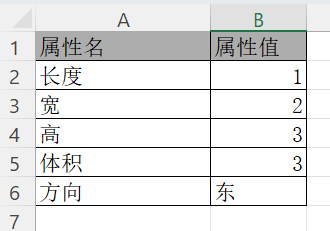

filename = 'Book1.xlsx';
warning off
dataTable = readtable(filename,ReadVariableNames=true)

dataTable = 5×2 table
      x___      x____1
    ________    ______
    {'长度'}       1  
    {'宽'  }       2  
    {'高'  }       3  
    {'体积'}       3  
    {'方向'}     NaN  

默认的读取方式，会将最后一行的文本读入为NaN

## 方案1

那我们可以在前面先用detectImportOptions命令查看相关信息，发现它会自动把第二列识别为double类型。

clear
filename = 'Book1.xlsx';
sheet = 1; % 要读取的工作表编号或名称
range = 'A:B'; % 要读取的单元格范围
%% 创建导入选项
opts = detectImportOptions(filename, 'Sheet', sheet, 'Range', range)

opts =   SpreadsheetImportOptions with properties:
   Sheet Properties:
                        Sheet: 1
   Replacement Properties:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'
         MergedCellColumnRule: 'placeleft'
            MergedCellRowRule: 'placetop'
   Variable Import Properties: Set types by name using setvartype
                VariableNames: {'x___', 'x____1'}
                VariableTypes: {'char', 'double'}
        SelectedVariableNames: {'x___', 'x____1'}
              VariableOptions: Show all 2 VariableOptions 
	

所以我们可以手动修改，让它都以字符串的方式读取，这样就能正确读入最后一行的【东】字了。

% 指定每列的数据类型
% 假设第一列和第二列都是文本类型
opts = setvartype(opts, {'x___', 'x____1'}, 'string');
% 使用 readtable 函数读取数据
dataTable = readtable(filename, opts);
% 显示读取的数据
disp(dataTable);

     x___     x____1
    ______    ______
    "长度"     "1"  
    "宽"       "2"  
    "高"       "3"  
    "体积"     "3"  
    "方向"     "东"  
